# **Behavior Models - Applied Example (Stateflow)**

**In this chapter, you will learn:**

- **How to create a behavior model, specific a stateflow machine.**

- **How to test a behavior model.**

As mentioned in the previous chapter, behavior models are highly benefical for model creation and testing. In this chapter, you will design your own behavior model. Please note that this chapter will focus exclusevily on explaining stateflows. We strongly recommend completing the onramp, accessible through the link provided. Additionaly, feel free to experiment with other behavior models, as each offers its own unique advantages: [**Stateflow Onramp Course**](https://matlabacademy.mathworks.com/details/stateflow-onramp/stateflow)

Stateflow is a tool that uses stateflow diagrams and tables to show how MATLAB algorithms and Simulink models respond to signals, events and time. It helps you design things like control systems, task scheduing, fault managements, and user intefaces. You can model decision logic, run it within Simulink or MATLAB, and use animations to debug as it runs. Stateflow also checks your design for errors during editing and execution to ensure it's ready form implementation.

With stateflow, you can design state machines using drag and drop elements and simple logic statements. Within state machines, you can use flow chats to represent state logic. A state is a condition or mode that the system can be in, and transitions between states happen based on certain event or conditions. 

                                                  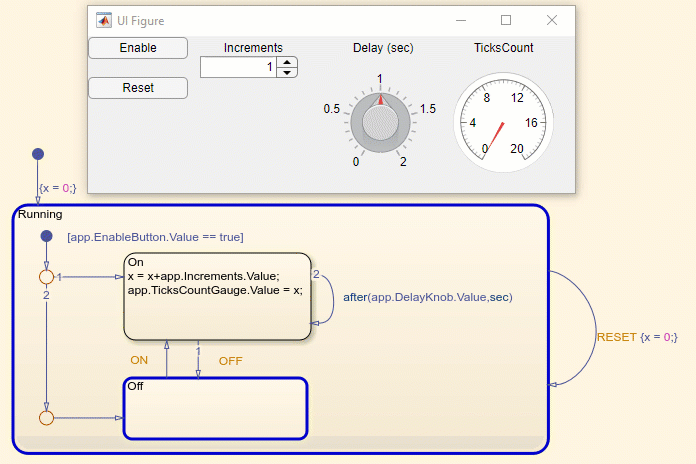                                           

The image above demonstrates the use of Stateflow in MATLAB. This is a more complex example as it interacts with a custom-built GUI (Graphical User Interface). This state machine, named "Running", has two states, where is specific actions are performed. State transitions are shown by blue lines, with each their condition. For instance, in transition 2, the event '*after (app.DelayKnob.Value,sec)'* is set, which points to the same state. This means that the transition occurs after the knob value from the GUI (ranging from 0-2) is reached in seconds. Each time this state is entered, the variable x is increade by the GUI's increment value and will be shown in the GUI's gauge. You can identify an active state by its ouline turning dark blue. In the example above, you'll notice the "On" state flickering, indicating that the system is entering this state multiple times. The system only transitions to the other state when "Enable" is pressed again, since the system then turns OFF. This may seem difficult at first, but as you create your own Stateflow machine, it will become clearer.

**Practical assignment**

Image you're an engineer at a space company tasked with designing a fixed flight path for an unmanned aerial vehicle (UAV). You decide to use Flowchart in Simulink, but you also want to convince your boss to adopt Stateflow for future projects. You explain that Stateflow offers more advanced control over statig logic, better visualization od transitions, and improved debugging tools. Your boss is open to the idea, as long as it meets the design requirements. He gave you simple system requirements so that you can prove Stateflow for the path planning:

- The Stateflow machine cannot contain more then 8 states.

- The Stateflow machine must contain an takeoff, and landing state where the UAV cannot move in any X or Y direction.

- The UAV must fly in a fixed square, meaning it should make a full 90-degree turn at each corner, completing four equal-length straight paths to form a closed loop. See picture below for the aimed goal.

                                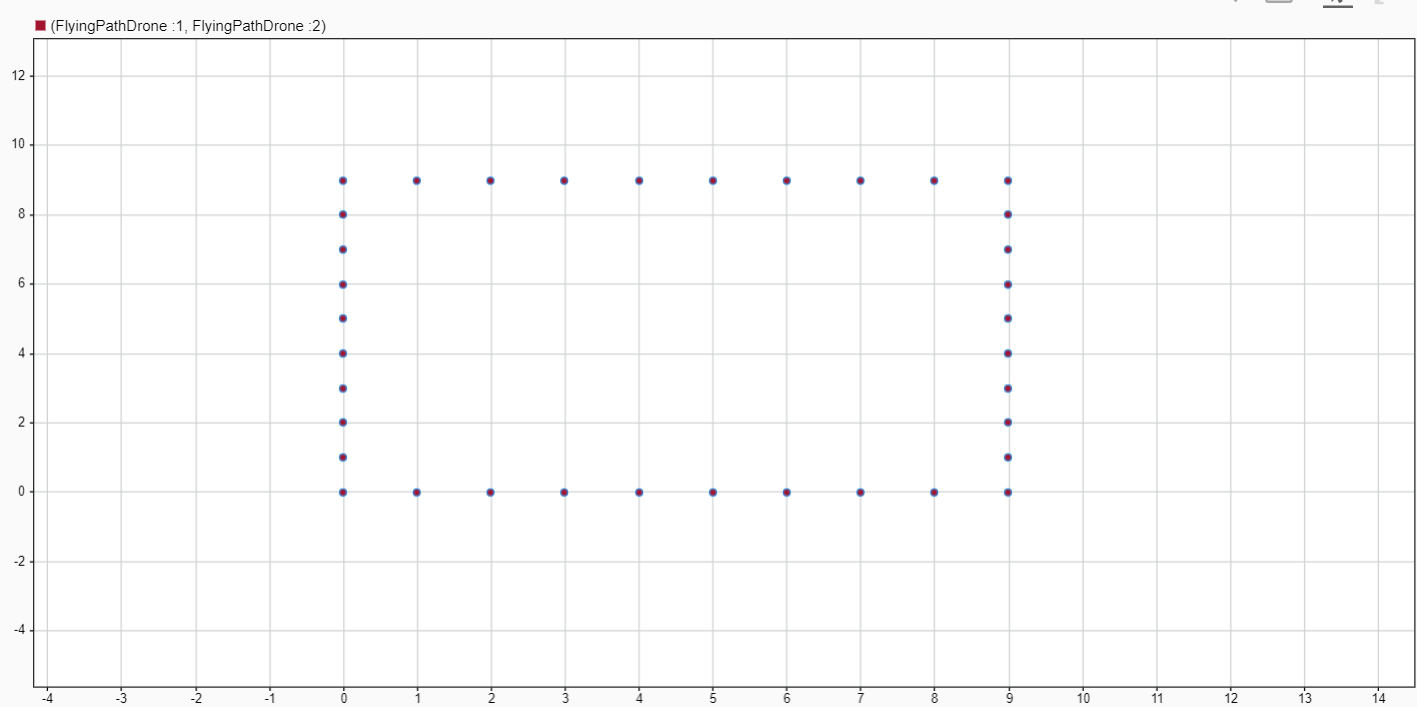

Click the button to open the project where you will design your state machine.

 
open("./Chapters/flightControl.slx")


Once opening the project, you will get the following Simulink model. The model represent different blocks The flying path state model is already made from you with the two takeoff and landing states, as required by your boss. The XY graph shows the 2D route of the UAV. Remember you try to fly a fixed square like the picture above. The other scope will show the three different directions of the UAV in one plot, so you can easily see what the behavior of the signals are regarding time. Remember the states limits of eight. 

                        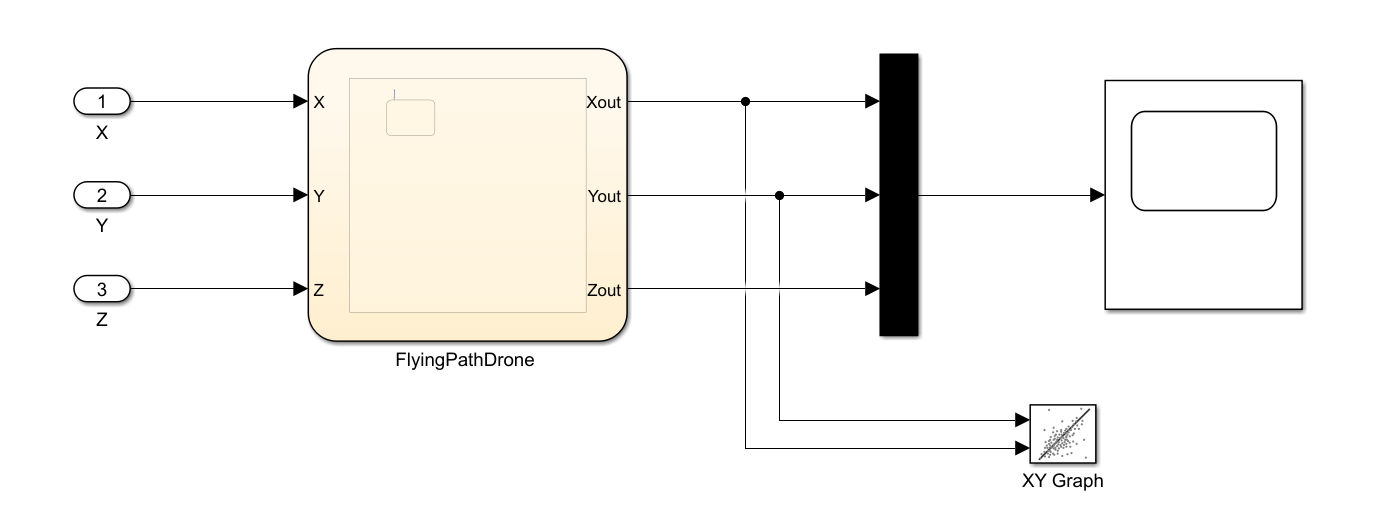

Here are some tips:

- Make seperate states for going straight and turning, reuse the states in order to complete the path.

- Use state transitions with after and use seconds e.g. after(2,sec). If you use the same state transition between every state you will end up getting a perfect square as flying path. You can set a transition condition to first make an arrow between components, double click on the arrow and select condition [].

- Only use the variable names Xout, Yout, Zout. Using other variable names will causes errors. Changing Zout will not be visibly in a graph so you can neglect this variable.

- Enable Simulation Pacing (under Run button). This allows you to clearly see the steps for your UAV. Keep the time per walk to just one second. Increasing the Stop Time can also helpful for extending your simulation duration. 

                                                                            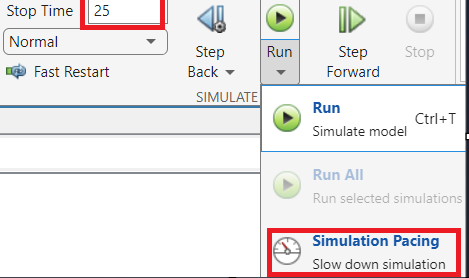

- Carefully code your states. Keep in mind that 'entry: ....'  sets the values when the system first enters the state, while 'during: ...' defines what happens while the system remains in that states. For example, to set up a straight path, you might start with something like the image below. In this example, the entry values are set to the current position of UAV, During the state execution, the X output is incremented, meaning that the UAV is flying straight.

                                                                                                            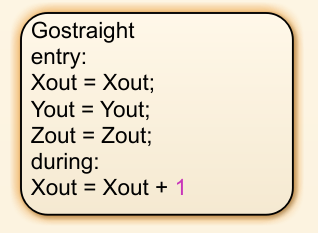               

Now it's your turn. Begin designing your state model and demonstrate to your boss that Stateflow is the ideal solution for future projects,

***Test your knowledge:***

""
correctAnswer1 = "State logic";
correctAnswer2 = "State Logic";
correctAnswer3 = "state logic";
correctAnswer4 = "STATE LOGIC";
correctAnswer5 = "state Logic";

% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) || strcmpi(ans, correctAnswer3) ||  strcmpi(ans, correctAnswer4) ||  strcmpi(ans, correctAnswer5) 
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

""
correctAnswer1 = "OFF";
correctAnswer2 = "Off";
correctAnswer3 = "off";

% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) || strcmpi(ans, correctAnswer3)
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

""
correctAnswer1 = "after(10,sec)";
correctAnswer2 = "[after(10,sec)]";

% Check if the user's input matches the correct answer
if strcmpi(ans, correctAnswer1) || strcmpi(ans, correctAnswer2) 
    disp('Congratulations! Your answer is correct.');
else
    disp('Sorry, your answer is incorrect. Try again!');
end

 
open("./Chapters/Recap.mlx")